# INTERPOLACJA

## CELE ZASTOSOWANIA INTERPOLACJI I APROKSYMACJI

Poniżej przedstawimy typowe problemy w jakich wykorzystuje się interpolację oraz aproksymację (w zależności od stanu danych wejściowych często te techniki w jakimś zakresie są komplementarne).

**1. ODWZOROWANIE KSZTAŁTU**

Odwzorowanie kształtu jest pod wieloma względami najważniejszym zastosowaniem interpolacji. Bardzo często podejście to jest w ogólności wbudowane w bardziej zaawansowane metody, które służą do rozwiązywania innych zagadnień. 

W tym wypadku najważniejszą informacją jaka nas interesuje jest błąd odwzorowania zależności oryginalnej pomiędzy węzłami interpolacji. Zwróćmy uwagę na poniższy kod - są tam wykonane dwie różne interpolacje. 

Zwróć uwagę, że choć obie spełniają formalną definicję interpolacji - obie funkcje interpolujące przechodzą przez wszystkie węzły, to jednak jest lepsza od drugiej pod względem odwzorowania funkcji oryginalnej. Musimy zatem poznać kryteria i wskazówki jak przeprowadzić operację interpolacji aby uzyskać optymalny wiarygodny wynik - sama umiejętność rozwiązania problemu interpolacji nie gwarantuje, że uzyskany wynik jest wiarygodny i od nas zależy taki dobór metody i jej parametrów aby uzyskać poprawny wynik.

%Na początek musimy przyjąć jaką zależność oryginalną. 
clear all;
%Interpolacji zawsze dokonujemy tylko na jakimś przedziale [a,b], u nas
%przyjmijmy:
a=1;
b=10;
N=9;
x=linspace(a,b,N);
funkcja='@(x)(log(x).*sin(x)./(x)).^2';
f=str2func(funkcja);
y=f(x);

%Wyrysujmy funkcję oryginalną
xx = linspace(a,b,101); %siatka do rysowania jest gęstsza niż ilość węzłów
plot(xx,f(xx),'k--');grid on;hold on;
%Dorysujmy położenia węzłów - punktów na podstawie których będziemy starali
%się odwzorować przebieg POMIĘDZY węzłami w jak najbardziej wiarygodny
%sposób
plot(x,y,'ro');

%1. Interpolacja "typu 1"
y_int1 = polyval(polyfit(x,y,(numel(x)-1)),xx);

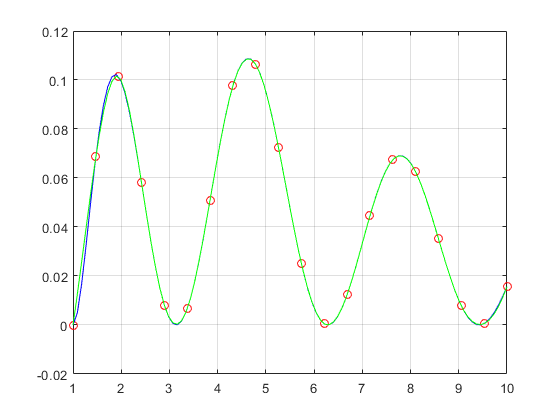

plot(xx,y_int1,'b')

%2. Interpolacja "typu 2"
y_int1 = spline(x,y,xx);
plot(xx,y_int1,'g'); hold off;

Przy takim postawieniu sprawy mamy następujące problemy, które musimy zaadresować i rozwiązać:

- W jaki sposób ilość węzłów (i ich rozłożenie) wpływa na jakość odwzorowania? - spróbuj pozmieniać wartość parametru N i obserwuj jak wraz ze zmianą ilość węzłów zmienia się jakość odwzorowania pomiędzy węzłami.

- W jaki sposób sama oryginalna funkcja (której zazwyczaj nie znamy) i jej właściwości wpływają na jakość odwzorowania? - powtórz poprzednie ćwiczenie zmieniając różne funkcje interpolowane - zwróć uwagę że w niektórych przypadkach zwiększenie ilość węzłów prowadzi do polepszenia jakości odwzorowania, a w innych wręcz odwrotnie. Spowodowane jest to różnymi właściwościami oryginalnej funkcji.

W przypadku danych wielowymiarowych - np. rozwiązań pól w przestrzeni, koncentracji, i innych parametrów fizycznych opisanych na przestrzeni (przykładowo danych z rezonansu magnetycznego) nie przechowujemy ich w postaci ciągłej na komputerze, ale w postaci tablic wartości opisanych na pewnej siatce w przestrzeni - przechowujemy tylko wartości w węzłach tych siatek:

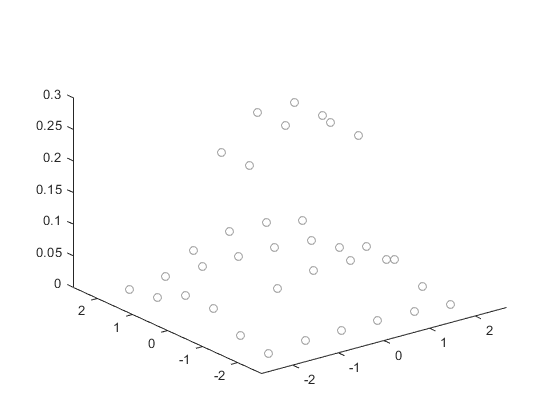

%Przykładowo wygenerujmy jakiś przebieg rozkładu wartości w przestrzeni 2D
%(może to być np. rozkład potencjału na powierzchni jakiegoś obiektu)
N=0.8;
[x, y] = meshgrid(-2:N:2,-2:N:2);
v = abs(x.*exp(-x.^2-y.^2));

[xq,yq] = meshgrid(-2:.2:2, -2:.2:2);
vq = griddata(x,y,v,xq,yq);

% Typowo tego typu dane reprezentowane są jako zbiór wartości  
plot3(x,y,v,'o','Color',[0.6 0.6 0.6]);
xlim([-2.7 2.7])
ylim([-2.7 2.7])

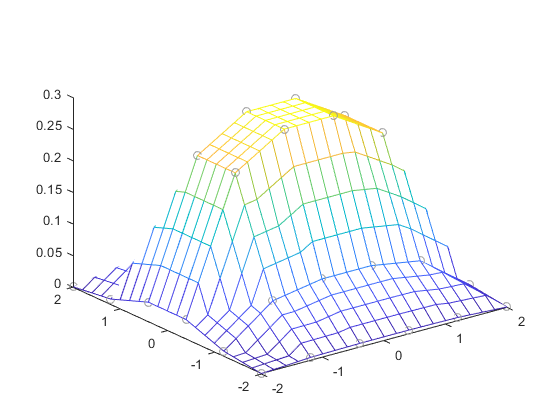

 
%Interpolacja wielowymiarowa opierająca się zasadniczo na poznanych przez
%nas technikach służy w dużej mierze do obrazowania i wyświetlania tego
%typu danych oraz uzyskiwania danych spoza węzłów

% To też jest rodzaj interpolacji, którego celem jest odwzorowanie kształtu
% - poniżej pokazano dwie reprezentacje po interpolacji - proszę zwrócić
% uwagę, że obie różnią się odwzorowaniem obiektu poza węzłami

%interpolacja "typu 1"
plot3(x,y,v,'o','Color',[0.6 0.6 0.6]);hold on;
mesh(xq,yq,vq);hold off;

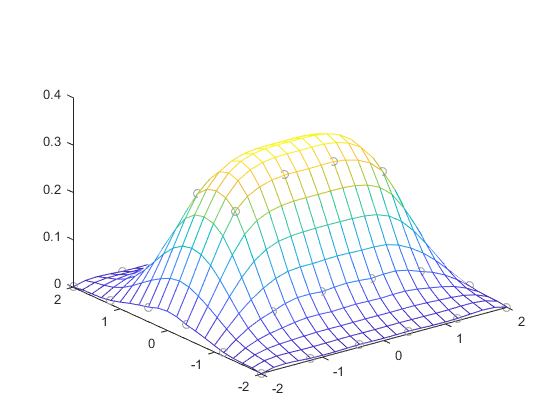


%interpolacja "typu 2"
vq = griddata(x,y,v,xq,yq,'v4');
plot3(x,y,v,'o','Color',[0.6 0.6 0.6]);hold on;
mesh(xq,yq,vq);hold off;

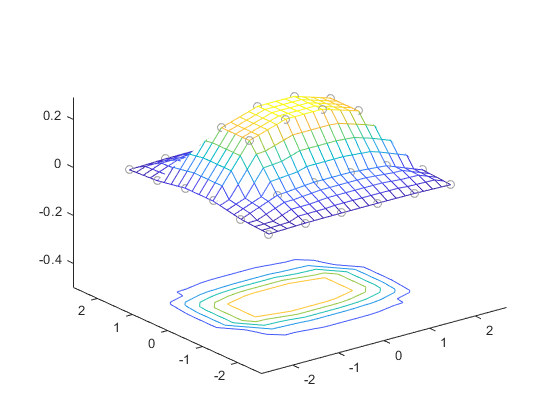


%Interpolacja jest też często wykorzystywana co operacji na reprezentacji
%tego typu danych, np. do generowani wykresów konturowych - generalnie
%zawsze wtedy gdy chcemy uzyskać wartości spoza węzłów. 

%TO ZASTOSOWANIE ITNERPOALCJI JEST KLUCZOWE DLA WIELU BARDZIEJ
%ZAAWANSOWANYCH METOD

%interpolacja "typu 1"
vq = griddata(x,y,v,xq,yq);
plot3(x,y,v,'o','Color',[0.6 0.6 0.6]);hold on;
mesh(xq,yq,vq);meshc(xq,yq,vq);hold off;
xlim([-2.7 2.7])
ylim([-2.7 2.7])
zlim([-0.5 Inf])

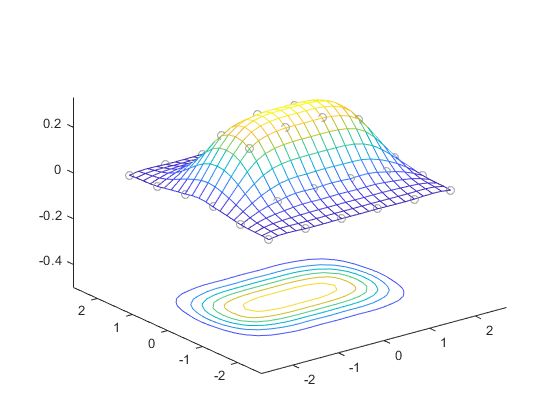


%interpolacja "typu 2"
vq = griddata(x,y,v,xq,yq,'v4');
plot3(x,y,v,'o','Color',[0.6 0.6 0.6]);hold on;
mesh(xq,yq,vq);meshc(xq,yq,vq);hold off;
xlim([-2.7 2.7])
ylim([-2.7 2.7])
zlim([-0.5 Inf])

Sprawdź, ze również w tym wypadku mamy do czynienia z dwom przedstawionymi wcześniej problemami:

- W jaki sposób ilość węzłów (i ich rozłożenie) wpływa na jakość odwzorowania? - spróbuj pozmieniać wartość parametru N i obserwuj jak wraz ze zmianą ilość węzłów zmienia się jakość odwzorowania pomiędzy węzłami.

- W jaki sposób sama oryginalna funkcja (której zazwyczaj nie znamy) i jej właściwości wpływają na jakość odwzorowania? - sprawdź, czy uda ci się wymyśleć taką funkcję interpolowaną, aby uzyskać duże różnice pomiędzy obiema interpolacjami

**2. Wyznaczenie parametrów modelu**

Ten problem najczęściej narasta dla danych pomiarowych. Dlatego też najczęściej stosuje się do jego rozwiązania metodę aproksymacji. Poniżej przytoczymy prosty przykład - problem pomiaru temperatury za pomocą termopary.

Została zmierzona charakterystyka termopary typu J (żelazo - konstantan) w celu wyznaczenia współczynnika termopary. Wiemy bowiem, że ten układ materiałów w mierzonych temperaturach powinien zachowywać się w sposób liniowy:


$$V=\textrm{aT}+b$$


napięcie na zaciskach termopary powinno być liniową funkcją temperatury. Musimy wyznaczyć współczynniki a i b w celu użytkowania takiej termopary i prowadzenia za jej pomocą pomiarów (robimy proces wzorcowania).

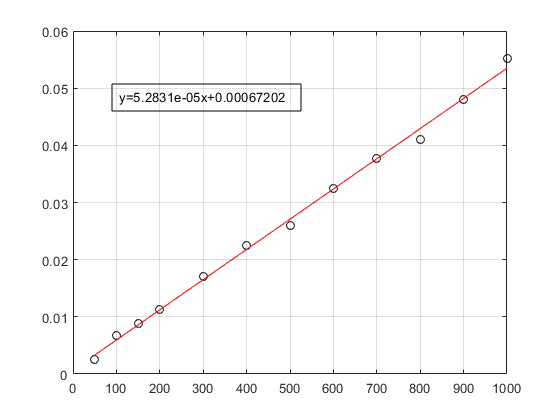

% Poniżej mamy nasze dane pomiarowe
Temp=[50;100;150;200;300;400;500;600;700;800;900;1000];

Voltage=[2.6;6.7;8.8;11.2;17;22.5;26;32.5;37.7;41;48;55.2]*1e-3;

% Wyrysujmy je - jak widzimy nie układają się one w linię prostą, ale
% raczej w jej okolicy. jest to wynikiem tego, że w pomiary wkradł się błąd
% o wartości niepomijalnej w stosunku do wymaganej przez nas dokładności
plot(Temp,Voltage,'ok');grid on;hold on;

% Dlatego będziemy starali się wyznaczyć prostą, która wprawdzie nie będzie
% przechodzić przez punkty, ale będzie starała się na ich podstawie
% wyeliminować różnicę pomiędzy rozłożeniem punktów, a przyjętym przez nas
% modelem. W tym celu posłużymy się rozwiązaniem problemu aproksymacji

% wyznaczenie współczynników linii aproksymującej
wsp = polyfit(Temp,Voltage,1);

% Wyrysujemy nasza wybraną linię
plot(Temp,polyval(wsp, Temp),'r');
str=['y=', num2str(wsp(1)), 'x+',num2str(wsp(2))];sim = [0.2 0.5 0.3 0.3];
annotation("textbox",sim,'String',str,'FitBoxToText','on');hold off;


 

Takiego podejścia możemy też użyć do weryfikacji. Przykładowo wraz z narażeniem temperaturowym skąd termopary się zmienia, a jej charakterystyka ulega zniekształceniu w stosunku do oryginalnej co powoduje błędy pomiarowe. 

Przykładowo dla termopary typu J nachylenie powinno się zawierać w okolicy 39-47 uV/C w zależności od zakresu temperaturowego pomiarów. Zatem jak widzimy nasza termopara może być już zakwalifikowana jako uszkodzona.

Tego typu podejście jest również szeroko stosowane w analizie danych nieposiadających ścisłych matematycznych modeli np. danych z zakresu nauk ekonomicznych, biologicznych czy socjalnych. Przykładowo poniżej przedstawiono dane z badania objętości płuc wśród dzieci w wieku 3-17 lat. Naszym celem jest znalezienie ogólenej reguły (na raize nie przejmujemy się rozrzutem):

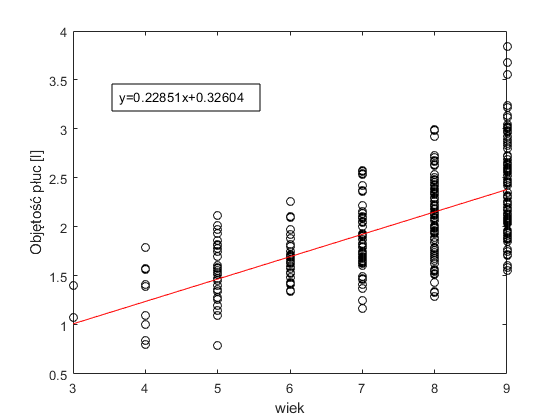

%Nasze dane
Age=[9	8	7	9	9	8	6	6	8	9	6	8	8	8	8	7	5	6	9	9	5	5	4	7	9	3	9	5	8	9	5	9	8	7	5	8	9	8	8	8	9	8	5	8	5	9	7	8	6	8	5	9	9	8	6	9	9	7	4	8	8	8	6	4	8	6	9	7	5	9	8	8	9	9	9	7	5	5	9	6	7	6	8	8	7	8	7	9	5	9	9	9	7	8	8	9	9	9	7	8	8	7	9	4	9	6	8	6	7	7	8	7	7	7	7	8	7	5	8	7	9	7	7	6	8	8	8	9	7	8	9	8	8	9	8	6	6	8	9	5	7	9	6	9	9	9	6	8	9	8	8	9	9	9	7	8	6	9	9	9	7	8	5	8	9	6	9	6	8	5	7	7	4	9	8	9	9	9	5	9	7	6	9	9	9	7	5	8	9	7	9	8	9	6	6	8	9	5	6	6	9	7	9	8	5	7	6	9	7	9	9	8	9	7	9	4	9	5	8	9	8	3	9	8	6	9	8	8	7	6	8	9	4	7	8	8	9	6	8	6	8	9	8	7	9	8	7	9	8	9	6	8	9	8	9	9	8	7	5	7	8	9	9	6	8	7	9	7	7	5	9	9	8	8	9	6	7	5	9	5	7	6	8	7	8	4	8	5	8	7	7	9	9	8	9	6	8	9	4	6	7	9	8	6	8	7	5	8	7];
Vol=[1.70800000000000	1.72400000000000	1.72000000000000	1.55800000000000	1.89500000000000	2.33600000000000	1.91900000000000	1.41500000000000	1.98700000000000	1.94200000000000	1.60200000000000	1.73500000000000	2.19300000000000	2.11800000000000	2.25800000000000	1.93200000000000	1.47200000000000	1.87800000000000	2.35200000000000	2.60400000000000	1.40000000000000	1.25600000000000	0.839000000000000	2.57800000000000	2.98800000000000	1.40400000000000	2.34800000000000	1.75500000000000	2.98000000000000	2.10000000000000	1.28200000000000	3	2.67300000000000	2.09300000000000	1.61200000000000	2.17500000000000	2.72500000000000	2.07100000000000	1.54700000000000	2.00400000000000	3.13500000000000	2.42000000000000	1.77600000000000	1.93100000000000	1.34300000000000	2.07600000000000	1.62400000000000	1.34400000000000	1.65000000000000	2.73200000000000	2.01700000000000	2.79700000000000	3.55600000000000	1.70300000000000	1.63400000000000	2.57000000000000	3.01600000000000	2.41900000000000	1.56900000000000	1.69800000000000	2.12300000000000	2.48100000000000	1.48100000000000	1.57700000000000	1.94000000000000	1.74700000000000	2.06900000000000	1.63100000000000	1.53600000000000	2.56000000000000	1.96200000000000	2.53100000000000	2.71500000000000	2.45700000000000	2.09000000000000	1.78900000000000	1.85800000000000	1.45200000000000	3.84200000000000	1.71900000000000	2.11100000000000	1.69500000000000	2.21100000000000	1.79400000000000	1.91700000000000	2.14400000000000	1.25300000000000	2.65900000000000	1.58000000000000	2.12600000000000	3.02900000000000	2.96400000000000	1.61100000000000	2.21500000000000	2.38800000000000	2.19600000000000	1.75100000000000	2.16500000000000	1.68200000000000	1.52300000000000	1.29200000000000	1.64900000000000	2.58800000000000	0.796000000000000	2.57400000000000	1.97900000000000	2.35400000000000	1.71800000000000	1.74200000000000	1.60300000000000	2.63900000000000	1.82900000000000	2.08400000000000	2.22000000000000	1.47300000000000	2.34100000000000	1.69800000000000	1.19600000000000	1.87200000000000	2.21900000000000	2.42000000000000	1.82700000000000	1.46100000000000	1.33800000000000	2.09000000000000	1.69700000000000	1.56200000000000	2.04000000000000	1.60900000000000	2.45800000000000	2.65000000000000	1.42900000000000	1.67500000000000	1.94700000000000	2.06900000000000	1.57200000000000	1.34800000000000	2.28800000000000	1.77300000000000	0.791000000000000	1.90500000000000	2.46300000000000	1.43100000000000	2.63100000000000	3.11400000000000	2.13500000000000	1.52700000000000	2.29300000000000	3.04200000000000	2.92700000000000	2.66500000000000	2.30100000000000	2.46000000000000	2.59200000000000	1.75000000000000	1.75900000000000	1.53600000000000	2.25900000000000	2.04800000000000	2.57100000000000	2.04600000000000	1.78000000000000	1.55200000000000	1.95300000000000	2.89300000000000	1.71300000000000	2.85100000000000	1.62400000000000	2.63100000000000	1.81900000000000	1.65800000000000	2.15800000000000	1.78900000000000	3.00400000000000	2.50300000000000	1.93300000000000	2.09100000000000	2.31600000000000	1.70400000000000	1.60600000000000	1.16500000000000	2.10200000000000	2.32000000000000	2.23000000000000	1.71600000000000	1.79000000000000	1.14600000000000	2.18700000000000	2.71700000000000	1.79600000000000	1.95300000000000	1.33500000000000	2.11900000000000	1.66600000000000	1.82600000000000	2.70900000000000	2.87100000000000	1.09200000000000	2.26200000000000	2.10400000000000	2.16600000000000	1.69000000000000	2.97300000000000	2.14500000000000	1.97100000000000	2.09500000000000	1.69700000000000	2.45500000000000	1.92000000000000	2.16400000000000	2.13000000000000	2.99300000000000	2.52900000000000	1.72600000000000	2.44200000000000	1.10200000000000	2.05600000000000	1.80800000000000	2.30500000000000	1.96900000000000	1.55600000000000	1.07200000000000	2.04200000000000	1.51200000000000	1.42300000000000	3.68100000000000	1.99100000000000	1.89700000000000	1.37000000000000	1.33800000000000	2.01600000000000	2.63900000000000	1.38900000000000	1.61200000000000	2.13500000000000	2.68100000000000	3.22300000000000	1.79600000000000	2.01000000000000	1.52300000000000	1.74400000000000	2.48500000000000	2.33500000000000	1.41500000000000	2.07600000000000	2.43500000000000	1.72800000000000	2.85000000000000	1.84400000000000	1.75400000000000	1.34300000000000	2.30300000000000	2.24600000000000	2.47600000000000	3.23900000000000	2.45700000000000	2.38200000000000	1.64000000000000	1.58900000000000	2.05600000000000	2.22600000000000	1.88600000000000	2.83300000000000	1.71500000000000	2.63100000000000	2.55000000000000	1.91200000000000	1.87700000000000	1.93500000000000	1.53900000000000	2.80300000000000	2.92300000000000	2.35800000000000	2.09400000000000	1.85500000000000	1.53500000000000	2.13500000000000	1.93000000000000	2.18200000000000	1.35900000000000	2.00200000000000	1.69900000000000	2.50000000000000	2.36600000000000	2.06900000000000	1.41800000000000	2.33300000000000	1.51400000000000	1.75800000000000	2.53500000000000	2.56400000000000	2.48700000000000	1.59100000000000	1.62400000000000	2.79800000000000	1.69100000000000	1.99900000000000	1.86900000000000	1.00400000000000	1.42700000000000	1.82600000000000	2.68800000000000	1.65700000000000	1.67200000000000	2.01500000000000	2.37100000000000	2.11500000000000	2.32800000000000	1.49500000000000];


% Wyrysujmy nasze dane i zwróćmy uwagę na fakt, że zasadniczo nie jest to
% funkcja - dla danych tych mamy wiele punktów dla każdej wartości x
plot(Age, Vol, 'ko');xlabel("wiek"); ylabel("Objętość płuc [l]");hold on;

% Ponieważ aproksymacja i interpolacja choć wyglądają podobnie z punktu
% widzenia rozwiązania problemu to są zdefiniowane zupełnie inaczej. Z tym
% problemem interpolacja nie mogłaby sobie poradzić, bo żadna funkcja nie
% może przejść przez wszystkie punkty. 

% Natomiast znakomicie radzi sobie z nim aproksymacja i dlatego jest
% najczęściej w zagadnieniach identyfikacji parametrów modelu wykorzystywana
wsp = polyfit(Age,Vol,1);
plot(Age,polyval(wsp, Age),'r');
str=['y=', num2str(wsp(1)), 'x+',num2str(wsp(2))];sim = [0.2 0.5 0.3 0.3];
annotation("textbox",sim,'String',str,'FitBoxToText','on');hold off;

% Widzimy w ten sposób jaka jest średnia objętość płuc w populacji w skali
% wieku. A to już jest cenna i użyteczna informacja.

% Zwróć uwagę, że model przyjęliśmy arbitralnie - nie ma żadnych
% fizycznych opisów pokazujących jak powinno to wyglądać. Jest to stricte
% matematyczne modelowanie

 

**APROKSYMACJA A REGRESJA**

Aproksymacja i regresja to nie jest to samo. Zagadnienie regresji oprócz metod wyznaczania współczynników modeli potrafi też oszacować statystyczne właściwości problemu takie jak średnią i maksymalną dewiację od wartości średniej, jakoś odwzorowania wyrażoną za pomocą odpowiednich miar statystycznych.

Przykładowo w problemie objętości płuc w funkcji wieku za pomocą aproksymacji uzyskaliśmy parametry modelu liniowego. Nie wiemy natomiast czy jest to wartość wiarygodna, jaki jest zakres, który można uznać za akceptowalny, a jakie wyniki badań powinny nas martwić itd. 

Regresja jest zatem problemem szerszym, chodź w pewnych wypadkach korzysta z aproksymacji. Można powiedzieć, że aproksymacja jest szczególnym prostym przypadkiem regresji w zakresie wyznaczania parametrów modelu. Niemniej ma ona liczne ograniczenia - głównym jest konieczność przyjęcia funkcji z jakiegoś ciągu jako stałego parametru implementacyjnego, co nie zawsze współgra z różnymi modelami. Dlatego metody regresyjne są zazwyczaj bardziej skomplikowane od samej aproksymacji.

**3. DYSKRETNA TRANSFORMATA FOURIERA**

Dyskretna transformata Fouriera jest narzędziem leżącym u podstawy cyfrowego przetwarzania sygnałów. Z punktu widzenia matematycznego jest to również interpolacja, ale taka, której baza - czyli ciąg funkcji interpolujących dobrana jest w pewien specyficzny sposób zgodny z teorią sygnałów. DFT posiada własne specjalizowane metody numeryczne opierające się na jej unikalnych właściwościach. Ze względu na znaczenie tego mechanizmu w elektronice będziemy o nim mówili trochę więcej.

Prostym przykładem zastosowania transformaty DFT są filtry cyfrowe np. filtry audio:

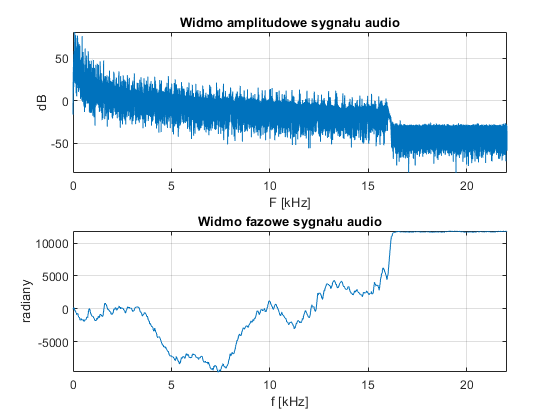

% Wczytamy próbkę dźwięku
Fs = 44100;
y = audioread('guitartune.wav');

% Obliczamy N-punktową transformatę DFTz tego sygnału - jest to rodzaj
% interpolacji
NFFT = length(y);
Y = fft(y,NFFT);
F = ((0:1/NFFT:1-1/NFFT)*Fs).';


% Wyświetlmy widma częstotliwościowe tego sygnału - widmem nazywamy zbiór
% współczynników będących rezultatami obliczenia transformaty - czyli
% naszych pk
magnitudeY = abs(Y);        % Magnitude of the FFT
phaseY = unwrap(angle(Y));  % Phase of the FFT

helperFrequencyAnalysisPlot1(F,magnitudeY,phaseY,NFFT);

%Brzmi on następująco
y1 = ifft(Y,NFFT,'symmetric');
hplayer = audioplayer(y1, Fs);
play(hplayer);
 

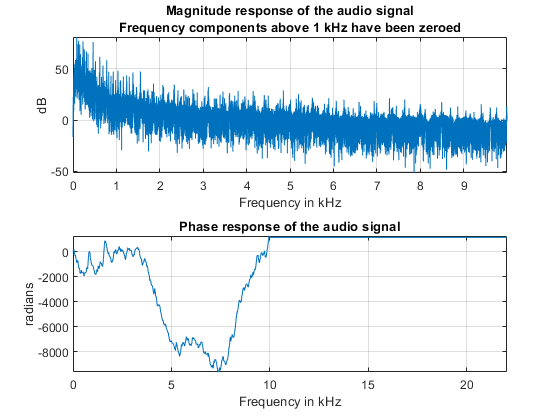


%Dzięki DFT możemy wykonywać operacje w dziedzinie częstotliwości, np.
%usunąć wszystkie składowe powyżej 0.5 kHz

Ylp = Y;
f_cutoff = 500;
Ylp(F>=f_cutoff & F<=Fs-f_cutoff) = 0;

helperFrequencyAnalysisPlot1(F,abs(Ylp),unwrap(angle(Ylp)),NFFT,...
  'Frequency components above 0.5 kHz have been zeroed');
ylp = ifft(Ylp,'symmetric');
hplayer = audioplayer(ylp, Fs);
play(hplayer);
 

**Zwróć uwagę, że choć DFT jest z matematycznego punktu widzenia interpolacją, to jej celem nie jest maksymalnie dobre odwzorowanie kształty przebiegu, a jest nim wyznaczenie w sposób możliwie wiarygodny współczynników korelacji miedzy sygnałem a bazą specjalnie przygotowanych funkcji okresowych. Dlatego też metody jego obliczania są znacznie różne od interpolacji przeznaczonej do odwzorowania kształtu.**

## Używane funkcje

function helperFrequencyAnalysisPlot1(F,Ymag,Yangle,NFFT,ttlMag,ttlPhase)
% Plot helper function for the FrequencyAnalysisExample

% Copyright 2012 The MathWorks, Inc.

figure
subplot(2,1,1)
plot(F(1:NFFT/2)/1e3,20*log10(Ymag(1:NFFT/2)));
if nargin > 4 && ~isempty(ttlMag)
  tstr = {'Widmo amplitudowe sygnału audio',ttlMag};
else
  tstr = {'Widmo amplitudowe sygnału audio'};
end
title(tstr)
xlabel('F [kHz]')
ylabel('dB')
grid on;
axis tight 
subplot(2,1,2)
plot(F(1:NFFT/2)/1e3,Yangle(1:NFFT/2));
if nargin > 5
  tstr = {'Widmo fazowe sygnału audio',ttlPhase};
else  
  tstr = {'Widmo fazowe sygnału audio'};
end
title(tstr)
xlabel('f [kHz]')
ylabel('radiany')
grid on;
axis tight
end